# 4

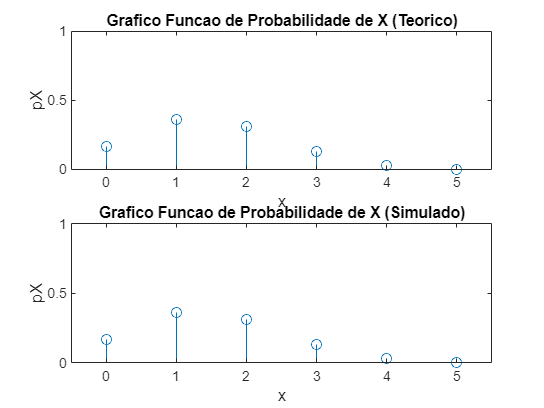

% Prob("peca ser defeituosa") = 30%

%X = # de pecas defeituosas numa amostra de 5 pecas escolhidas aleatoriamente

%Sx = {0, 1, 2, 3, 4, 5}

% Podemos considerar que X demonstra uma distribuicao biniomial visto que podemos 
%considerar que e constituido por varias experiencias de bernoulli onde sucesso
%corresponde a "sair uma peca defeituosa"

%% a)

%Analiticamente:

%Como X e uma variavel Binomial: %pX(k) = nCk * p^k * (1-p)^(n-k) = n! / (k! * (n-k)!) * p^k * (1-p)^(n-k)

pXTeorica = zeros(1,6);
n = 5;   %Numero de pecas escolhidas
p = 3/10; %Probabilidade da peca ser defeituosa (=30/100 = 30%)

for k=0 : 5
  i = k+1;
  nCk = factorial(n)/(factorial(k) * factorial(n-k));
  pXTeorica(i) = nCk * p^k * (1-p)^(n-k);
end

pXTeorica;

figure(1);
hold on;

x = 0:5;

subplot(2,2,[1,2]);

stem(x,pXTeorica);

axis([-0.5 5.5 0 1]);
xlabel('x');
ylabel('pX');
title("Grafico Funcao de Probabilidade de X (Teorico)");

%Por Simulacao

N = 1e5;
pXSim = zeros(1,6);

for k=0 : 5
  i = k+1;
  pXSim(i) = fMassaProb(N,p,k,n);
end

subplot(2,2,[3,4]);

stem(x,pXSim);

axis([-0.5 5.5 0 1]);
xlabel('x');
ylabel('pX');
title("Grafico Funcao de Probabilidade de X (Simulado)");

## b

%Analiticamente:
disp("Analiticamente:");

Analiticamente:



p = pXTeorica(1) + pXTeorica(2) + pXTeorica(3);
fprintf("P(Termos no maximo 2 pecas defeituosas) = %f\n",p);

P(Termos no maximo 2 pecas defeituosas) = 0.836920



%Por Simulacao
disp("\nPor Simulacao::");

\nPor Simulacao::



p = pXSim(1) + pXSim(2) + pXSim(3);
fprintf("P(Termos no maximo 2 pecas defeituosas) = %f\n",p);

P(Termos no maximo 2 pecas defeituosas) = 0.843510
